%Using the Matlab Symbolic Toolbox to solve for properties of parametric
%curves
clc, clear all

%For this demo code, we will solve for the parametric circle that is
%presented in Robo Night 1

%First we must define the symbolic variables we will being using
syms R u r
% u = [0, 3.2]

%Define the equation for the parametric circle. For clarity, I am first 
%creating individual equations for r in the i, j, and k direction, 
%then packing them in one vector. In this case, we are
%creating a 1x3 vector that has symbolic equations for the i, j, and k
%components of the equation, respectively. Note that the k component in
%this case is just equal to 0. We use 0*u because if we substitute a vector
%of numerical values in for the symbolic u at a later time, the dimensions
%of the vector will be consistent.
ri= 4 * 0.396*cos(2.65(u + 1.4));
rj= 4 * 0.99**sin(u + 1.4);
rk= 0 * u;
r=[ri,rj,rk];

%to take the derivative, we use the diff function in Matlab, with the
%inputs being diff(function,variable to differentiate)
dr=diff(r,u);

%To find the unit tangent we divide by the magnitude of r'=dr. To make this
%result look nice, we want to add some assumptions
assume(R,{'real','positive'})
assume(u,{'real','positive'})

%despite these assumptions, you will see that the unit tangent vector is a
%bit difficult to read (note I use the norm function, not abs)
T_hat_ugly=dr./norm(dr)

$$T\_hat\_ugly = \left(\begin{array}{ccc} -\frac{R\,\sin\left(u\right)}{\sqrt{R^{2}\,{\left|\cos\left(u\right)\right|}^{2}+R^{2}\,{\left|\sin\left(u\right)\right|}^{2}}} & \frac{R\,\cos\left(u\right)}{\sqrt{R^{2}\,{\left|\cos\left(u\right)\right|}^{2}+R^{2}\,{\left|\sin\left(u\right)\right|}^{2}}} & 0 \end{array}\right)$$


%We can use the simplify function to make things look nice
T_hat=simplify(T_hat_ugly)

$$T\_hat = \left(\begin{array}{ccc} -\sin\left(u\right) & \cos\left(u\right) & 0 \end{array}\right)$$


%Next, we want to find the unit normal vector
dT_hat=diff(T_hat,u);
N_hat=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat)

$$N\_hat = \left(\begin{array}{ccc} -\cos\left(u\right) & -\sin\left(u\right) & 0 \end{array}\right)$$


%The unit binormal vector is found from the cross product of the unit
%tangent and unit normal
B_hat=cross(T_hat,N_hat);
B_hat=simplify(B_hat)

$$B\_hat = \left(\begin{array}{ccc} 0 & 0 & 1 \end{array}\right)$$


%We can also find the curvature
kappa=norm(dT_hat)/norm(dr);
kappa=simplify(kappa)

$$kappa = \frac{1}{R}$$


%How about the Torsion?
tau=-N_hat*(diff(B_hat,u)/norm(dr))'

$$tau = 0$$

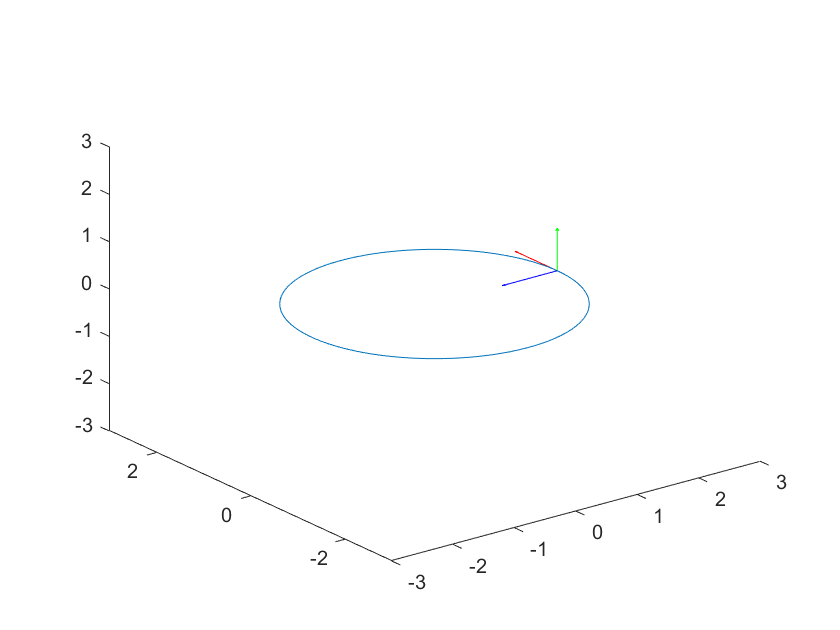

%If we wish to visualize this curve, we can make substitutions into our
%functions. 
R_num = 2;% define a specific radius
u_num = linspace(0,2*pi,100); % define a set of evenly spaced points between 0 and 2*pi

%we will also convert to a number of type double
for n=1:length(u_num)
    r_num(n,:)=double(subs(r,[R, u],[R_num, u_num(n)]));
    T_hat_num(n,:)=double(subs(T_hat,[R, u],[R_num, u_num(n)]));
    N_hat_num(n,:)=double(subs(N_hat,[R, u],[R_num, u_num(n)]));
    B_hat_num(n,:)=double(subs(B_hat,[R, u],[R_num, u_num(n)]));
    
    %we can also plot this using the quiver3 function
    plot3(r_num(:,1),r_num(:,2),r_num(:,3)), axis([-3 3 -3 3 -3 3]),hold on % plot the entire curve
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),T_hat_num(n,1),T_hat_num(n,2),T_hat_num(n,3),'r') % plot the unit tangent
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),N_hat_num(n,1),N_hat_num(n,2),N_hat_num(n,3),'b') % plot the unit normal
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),B_hat_num(n,1),B_hat_num(n,2),B_hat_num(n,3),'g'), hold off % plot the unit binormal
    drawnow % force the graphic to update as it goes
end